# Wavepath of direct wave


% Define a homogenerous velocity model, and the model parameters; 
nz=81;nx=201;dx=5;x = (0:nx-1)*dx; z = (0:nz-1)*dx;
vel=zeros(nz,nx)+1000;  
% source and receiver geometry
sx = (nx-1)/4*dx; sz = 0; 
gx=(0:2:(nx-1))*dx; gz=zeros(size(gx)); g=1:numel(gx); 
% FD params and source wavelet
nbc=40; nt=2001; dt=0.0005; t=(0:nt-1)*dt; isFS=false; 
freq=25; s=ricker(freq,dt);
% generate synthetics
tic;
seis=a2d_mod_abc28(vel,nbc,dx,nt,dt,s,sx,sz,gx,gz,isFS);
toc;

Elapsed time is 17.655991 seconds.


% plot vel, gather, trace
figure(1);set(gcf,'position',[0 0 1000 500]);
subplot(221);imagesc(x,z,vel);colorbar;xlabel('X (m)'); ylabel('Z (m)'); title('velocity');
figure(1);subplot(222);imagesc(gx,t,seis);colormap(gray);
ylabel('Time (t)');xlabel('X(m)'); title('seismic gather');
figure(1);subplot(223);plot(t,seis(:,76));xlabel('Time (t)'); title('seismic trace');
% compute wavepath
tic; 
wp=a2d_wavepath_abc28(seis(:,76),vel,nbc,dx,nt,dt,s,sx,sz,gx(76),gz(76)); 
toc;

Elapsed time is 15.510838 seconds.


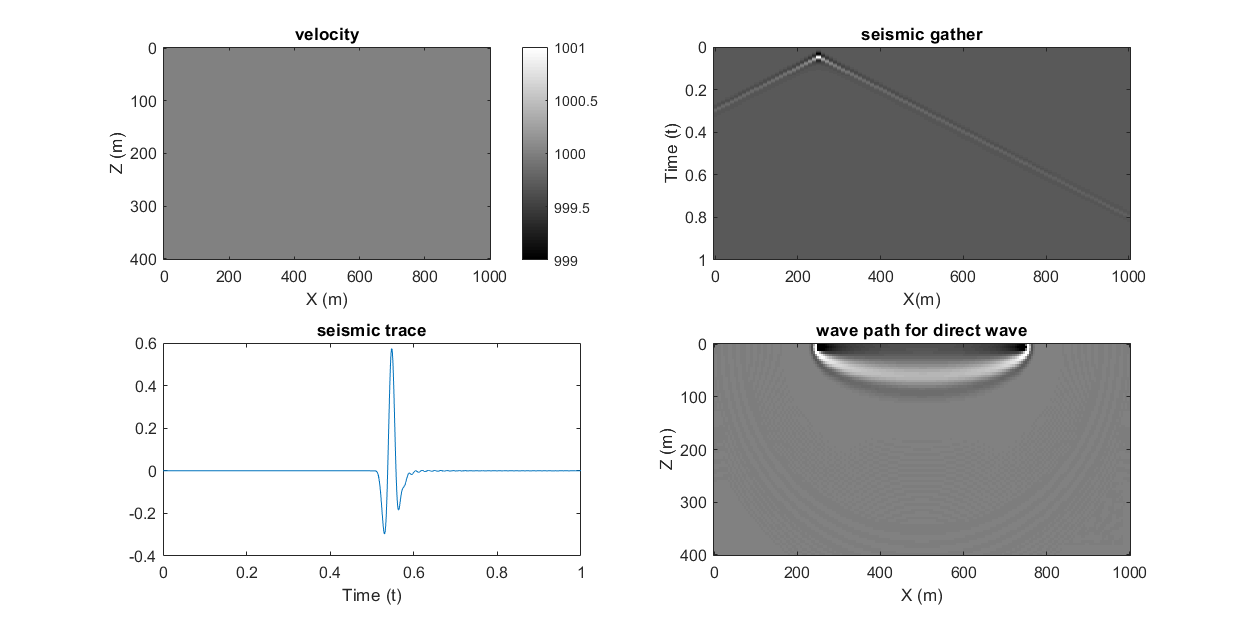

figure(1);subplot(224);imagesc(x,z,wp);colormap(gray);caxis([-10 10]);
xlabel('X (m)'); ylabel('Z (m)'); title('wave path for direct wave');

## Wavepath of diving wave


% Define a gradient velocity model, and the model parameters
vel=(1000:1000/150:2000);vel=repmat(vel',[1,401]);
[nz,nx]=size(vel);x = (0:nx-1)*dx; z = (0:nz-1)*dx; 
% source and receiver geometry
sx = (nx-1)/8*dx; sz = 0; 
gx=(0:2:nx-1)*dx; gz=zeros(size(gx)); g=0:numel(gx);
% FD params and source wavelet
nbc=40; nt=4001; dt=0.0005; t=(0:nt-1)*dt;isFS=false;freq=25; s=ricker(freq,dt);
% generate synthetics
tic; seis=a2d_mod_abc28(vel,nbc,dx,nt,dt,s,sx,sz,gx,gz,isFS);toc; 
% plot vel, gather, trace
figure(2);set(gcf,'position',[0 0 1000 500]);
subplot(221);imagesc(x,z,vel);colorbar;
xlabel('X (m)'); ylabel('Z (m)'); title('velocity');
figure(2);subplot(222);imagesc(gx,t,seis);colormap(gray);caxis([-1 1]);
ylabel('Time (t)'); xlabel('X (m)');title('seismic gather');
gx=gx(176);gz=gz(176); 
% mute direct wave
trace=seis(:,176); trace(2901:end)=0;
figure(2);subplot(223);plot(t,trace);
xlabel('Time (t)'); title('seismic trace with direct wave muted');
% compute wavepath
tic; wp=a2d_wavepath_abc28(trace,vel,nbc,dx,nt,dt,s,sx,sz,gx,gz); toc;
figure(2);subplot(224);imagesc(x,z,wp);colormap(gray);caxis([-0.1 0.1]);
xlabel('X (m)'); ylabel('Z (m)'); title('wave path for diving wave');

## Wavepath of refraction wave

% Define a two layer velocity model, and the model parameters; 
vel=[repmat(1000,[1 41]),repmat(2000,[1,80])];vel=repmat(vel',[1,401]);
[nz,nx]=size(vel);x = (0:nx-1)*dx; z = (0:nz-1)*dx;
% Define the source and receiver geometry;
sx = (nx-1)/8*dx; sz = 0; gx=(0:2:nx-1)*dx; gz=zeros(size(gx)); g=0:numel(gx);
% FD params
nbc=80; nt=4001; dt=0.0005; t=(0:nt-1)*dt;isFS=false;freq=25; s=ricker(freq,dt);
% generate synthetics
tic; seis=a2d_mod_abc28(vel,nbc,dx,nt,dt,s,sx,sz,gx,gz,isFS);toc; 
% mute late arrivals
trace=seis(:,176); trace(2801:end)=0;
figure(3);set(gcf,'position',[0 0 1000 500]);
subplot(221);imagesc(x,z,vel);colorbar;xlabel('X (m)'); ylabel('Z (m)'); title('velocity');
figure(3);subplot(222);
imagesc(gx,t,seis);colormap(gray);caxis([-0.025 0.025]);
title('seismic data');ylabel('Time (t)'); xlabel('X(m)');
figure(3);subplot(223);plot(t,trace);xlabel('Time (t)'); title('refraction wave');
% compute wavepath
tic; wp=a2d_wavepath_abc28(trace,vel,nbc,dx,nt,dt,s,sx,sz,gx(176),gz(176)); toc;
figure(3);subplot(224);imagesc(x,z,wp);colormap(gray);caxis([-0.0002 0.0002]);
xlabel('X (m)'); ylabel('Z (m)'); title('wave path for refraction wave');

## Wavepath of diffraction wave

% Define a point scatterrer model, and the model parameters
vel=zeros(101,201)+1000; vel(81,101)=1200;
[nz,nx]=size(vel);x = (0:nx-1)*dx; z = (0:nz-1)*dx;
sx = (nx-1)/8*dx; sz = 0; gx=(0:2:nx-1)*dx; gz=zeros(size(gx)); g=0:numel(gx);
nbc=80; nt=2601; dt=0.0005; t=(0:nt-1)*dt;isFS=false;freq=20; s=ricker(freq,dt);
% smooth the background velocity
[vel_ss,refl_ss]=vel_smooth(vel,3,3,1);
tic; seis=a2d_mod_abc28(vel,nbc,dx,nt,dt,s,sx,sz,gx,gz,isFS);toc; 
trace=seis(:,51); trace(1:1800)=0;trace(2301:end)=0;
figure(4);set(gcf,'position',[0 0 1000 500]);
subplot(221);imagesc(x,z,vel);colorbar;xlabel('X (m)'); ylabel('Z (m)'); title('velocity');
figure(4);subplot(222);imagesc(gx,t,seis(1:2601,:));colormap(gray);caxis([-0.025 0.025]);
ylabel('Time (t)'); xlabel('X (m)');title('seismic data for one trace');
figure(4);subplot(223);plot(t,trace);xlabel('Time (t)'); title('diffraction wave');
% compute wavepath
tic; wp=a2d_wavepath_abc28_refl(trace,vel_ss,refl_ss,nbc,dx,nt,dt,s,sx,sz,gx(51),gz(51)); toc;
figure(4);subplot(224);imagesc(x,z,wp);colormap(gray);caxis([-0.002 0.002]);
xlabel('X (m)'); ylabel('Z (m)'); title('wave path for diffraction wave');

## Wavepath of reflection wave


% Define a two layer model, and the model parameters
vel=zeros(101,201)+1000; vel(81:end,:)=1500;[nz,nx]=size(vel);x = (0:nx-1)*dx; z = (0:nz-1)*dx;
sx = (nx-1)/8*dx; sz = 0; gx=(0:2:nx-1)*dx; gz=zeros(size(gx)); g=0:numel(gx);
nbc=80; nt=2601; dt=0.0005; t=(0:nt-1)*dt;isFS=false;freq=20; s=ricker(freq,dt);
[vel_ss,refl_ss]=vel_smooth(vel,3,3,1);
tic; seis=a2d_mod_abc28(vel,nbc,dx,nt,dt,s,sx,sz,gx,gz,isFS);toc; 
trace=seis(:,76); trace(1:1800)=0;trace(2301:end)=0;
figure(5);set(gcf,'position',[0 0 1000 500]);
subplot(221);imagesc(x,z,vel);colorbar;
xlabel('X (m)'); ylabel('Z (m)'); title('velocity');
figure(5);subplot(222);imagesc(gx,t,seis(1:2601,:));colormap(gray);caxis([-0.1 0.1]);
ylabel('Time (t)'); xlabel('X (m)'); title('seismic data for one trace');
figure(5);subplot(223);plot(t,trace);xlabel('Time (t)'); title('reflection wave');
% compute wavepath
tic; wp=a2d_wavepath_abc28_refl(trace,vel,refl_ss,nbc,dx,nt,dt,s,sx,sz,gx(76),gz(76)); toc;
figure(5);subplot(224);imagesc(x,z,wp);colormap(gray);caxis([-2 2]);
xlabel('X (m)'); ylabel('Z (m)'); title('wave path for reflection wave');